# **Validation ADCP Data with Mohid Model**

Validate ADCP Demo script for comparing ADCP data with Mohid Model, 

This demo script will provide some examples of how to properly upload adcp data and compare with mohid model extracting a profile from either HDF5 we will add to read from ADCP support. 

Author: Mariangel Garcia (mariangel.garcia@tecnico.ulisboa.pt)

- Please try first with the example data and them try it with your own data

- Dowload data here and move it to the data directory:

 [https://ulisboa-my.sharepoint.com/:f:/r/personal/ist428189_tecnico_ulisboa_pt/Documents/dataMatlab?csf=1&e=1wDo7d](https://ulisboa-my.sharepoint.com/:f:/r/personal/ist428189_tecnico_ulisboa_pt/Documents/dataMatlab?csf=1&e=1wDo7d)

 Feel free to edit this file and adjust to your data.

10/01/2018

It required to donwload the ADCP profilers in  binary forms. 

It use https://www.eoas.ubc.ca/~rich/#RDADCP

the ADCP reader from the binary file:

%Add paths to the library to work for this file
clear; clc;
addpath(genpath('../../src/'))

## IMPUT files:

You just need to give your input in .bin file. 

%% lcoation of your ADCP FILE
ADCP_file='./data/SANE_000.000';
%Positions of your ADCP
Points=[-9.4676 38.6702];

% MOHID hdf5
MOHID_file='./data/Hydrodynamic_TagusValidation.hdf5';

% MOHID time series
%pth = './data/ADCP_mohid/';
%ext = 'Tagus_validation_ADCP2009_';
%depth_files='./data/depth/';
%ext_depth = 'Depth_';

% Athmosphere Data
% If you don't have it commented out.
csvFile='./data/windADPC2009.csv';

%Location of you Images
path_images = './images/'

path_images = './images/'

## READ Atmosphere data

If you don't have weather data just coment this line

[t_win,mag_win,deg_win,u_win,v_win,c_wind]=read_wind(csvFile);
plot_atmosphere(c_wind,t_win,u_win,v_win)

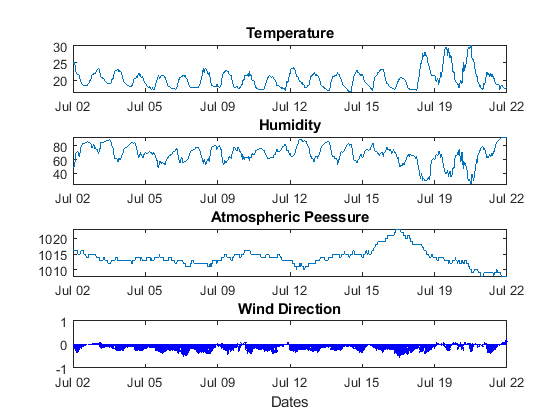

print([path_images 'Athmospheric_data'],'-dpng','-r0')

## Read ADCP Data

[ts_adcp,depth_adcp,u_adcp,v_adcp,mod_adcp,dir_adcp,temp_adcp,sal_adcp,press_adcp,adcp]=read_adcp(ADCP_file); 


Opening file ./data/SANE_000.000

 File comes from wh-adcp (firmware 16.21), source of data from: instrument
 4 Beams tilted at 20 degrees in a convex arrangement
 Acoustic Frequency: 600 kHz

 Cell size:  1.00, # cells: 44, deployed facing up
 Pings per ensemble: 50
 Data in earth coordinates

 Record begins at 02-Jul-2009 10:32:44
 Ping interval appears to be  00:15:00.000

Estimating 1938 ensembles in this file
   Reading 1938 ensembles, reducing by a factor of 5
Final result 387 values

 Simple mean used for ensemble averaging

    0.................................................
  250.................................................
  500.................................................
  750.................................................
 1000.................................................
 1250.................................................
 1500.................................................
 1750.....................................EOF reached after 1 bytes searched

[X_adcp,Y_adcp]=meshgrid(ts_adcp,depth_adcp);


## Plot ADCP Variables RAW Data

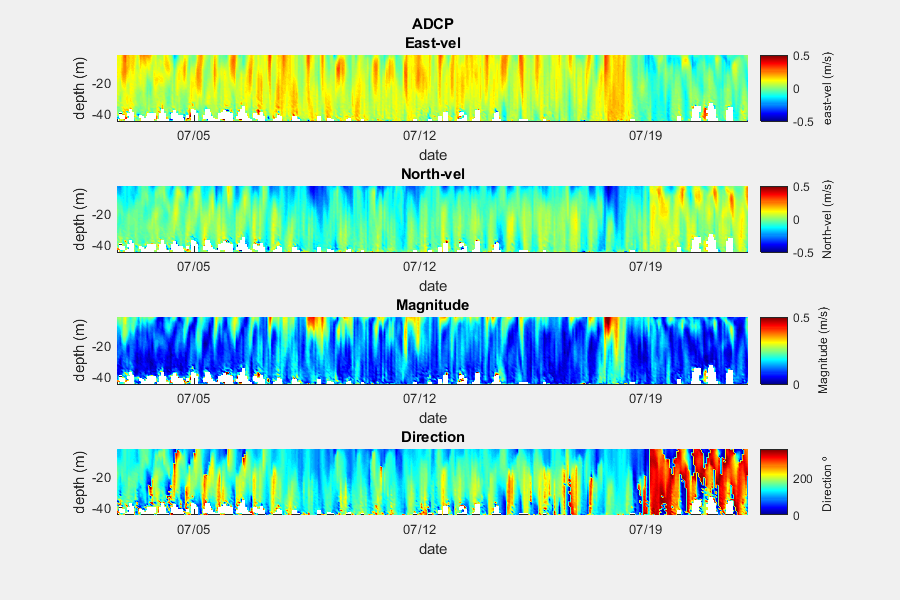

x_lim=[]; y_lim=[-40 0]; c_lim=[-0.5 0.5];
figure
plot_vertical_profile_time_all_vars(X_adcp,Y_adcp,u_adcp,v_adcp,mod_adcp,dir_adcp,y_lim,c_lim,'ADCP')
print([path_images 'Profile_ADCP_allVariables'],'-dpng','-r0')

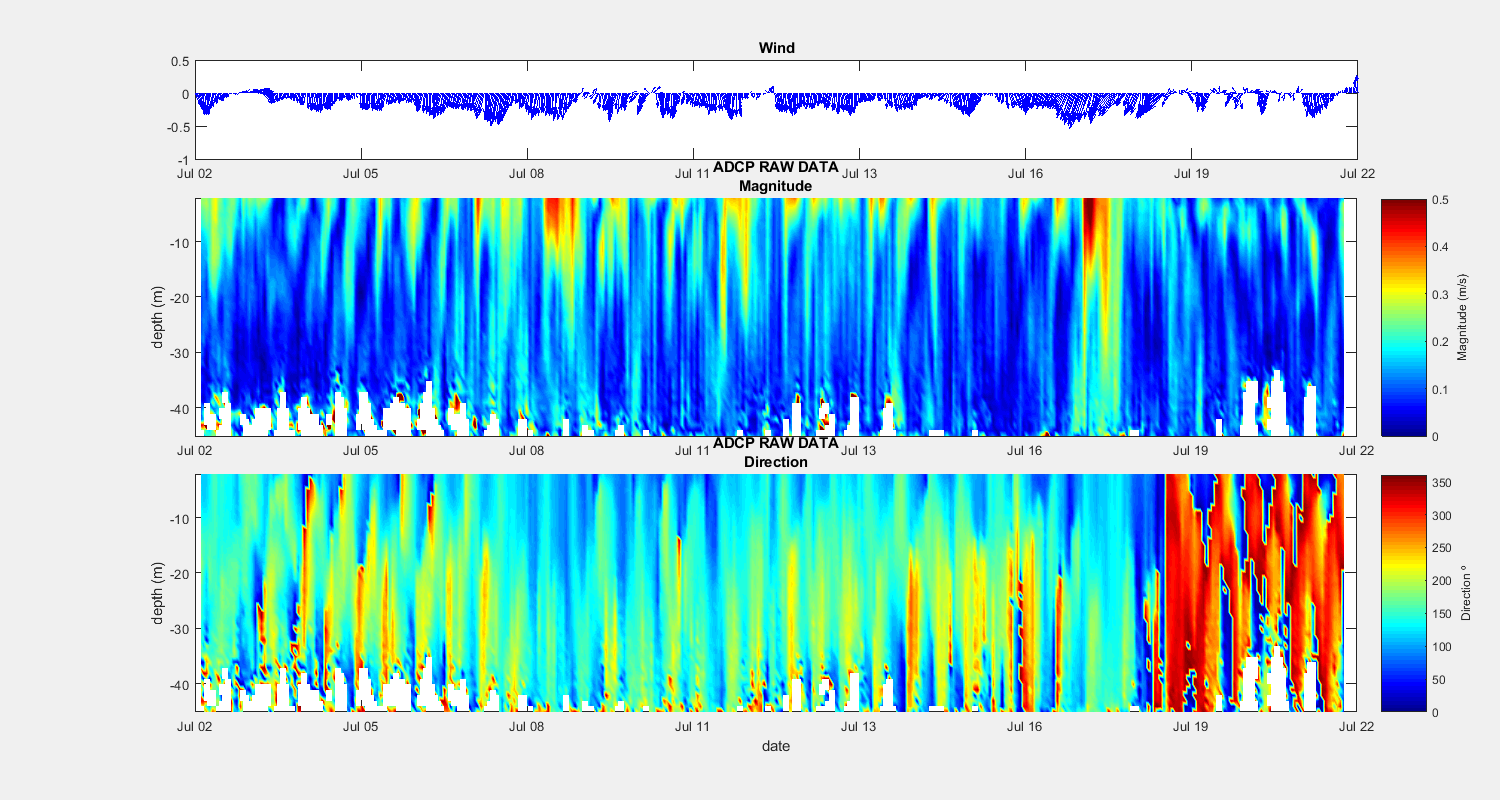


figure
%Plot with wind
plot_vertical_profile_time_all_vars_plus_wind(X_adcp,Y_adcp,mod_adcp,dir_adcp,t_win,u_win,v_win,y_lim,c_lim,'ADCP RAW DATA')
print([path_images 'Profile_ADCP_allVariables_with_wind'],'-dpng','-r0')

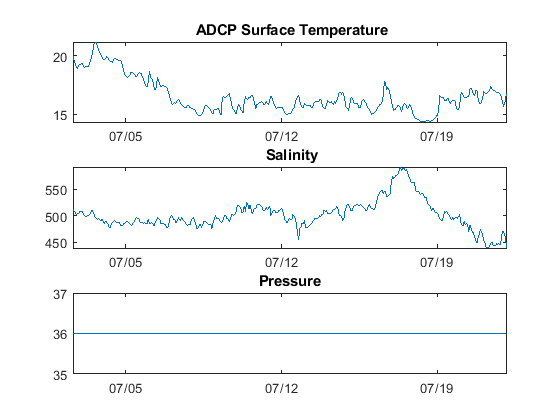


figure
subplot(3,1,1)
plot(ts_adcp,temp_adcp)
title(' ADCP Surface Temperature')
datetick('x')
axis tight
subplot(3,1,2)
plot(ts_adcp,sal_adcp)
title(' Salinity')
datetick('x')
axis tight
subplot(3,1,3)
plot(ts_adcp,press_adcp)
title('Pressure')
datetick('x')
axis tight

## Extract Profile from  Mohid  HDF5

%It will stract the profile at such giving point
%WARNING: This routine is extremly slow 
[ts_mh,depth_mh,u_mh,v_mh,mod_mh,dir_mh,wl]=read_profile_mohid_from_hdf5(MOHID_file,Points);

Loading from MOHID hdf5 output file
Reading Grid
Extracting U
Extracting V
Extracting WL
Done reading


## Read Profile from MOHID Time Series

Rigth now is not working,it needs to extract the entire time series with the sigmagrid depth.

%[t_ts,depth_ts,u_ts,v_ts,mod_ts,dir_ts,wl_ts]=read_profile_mohid_from_timeseries(pth,ext);
%[file,val,deph_sigma]=read_depths_from_files(depth_files,ext_depth);
%[X_ts,Y_ts]=meshgrid(t_ts,depth_ts);
%plot_vertical_profile_time_all_vars(X_ts,Y_ts,u_ts,v_ts,mod_ts,dir_ts,y_lim,c_lim,'MOHID from Time Series')

## Interpolate Mohid Sigma Grid Data into ADCP Grid

%Interpolate Over space
[uqq_mh,vqq_mh,modqq_mh,dirqq_mh,wlqq_mh]=interp_mohid2adcp(depth_mh,ts_mh,u_mh,v_mh,mod_mh,dir_mh,wl,ts_adcp,depth_adcp);


**Plot MOHID Profile Data interpolated in ADCP Grid**

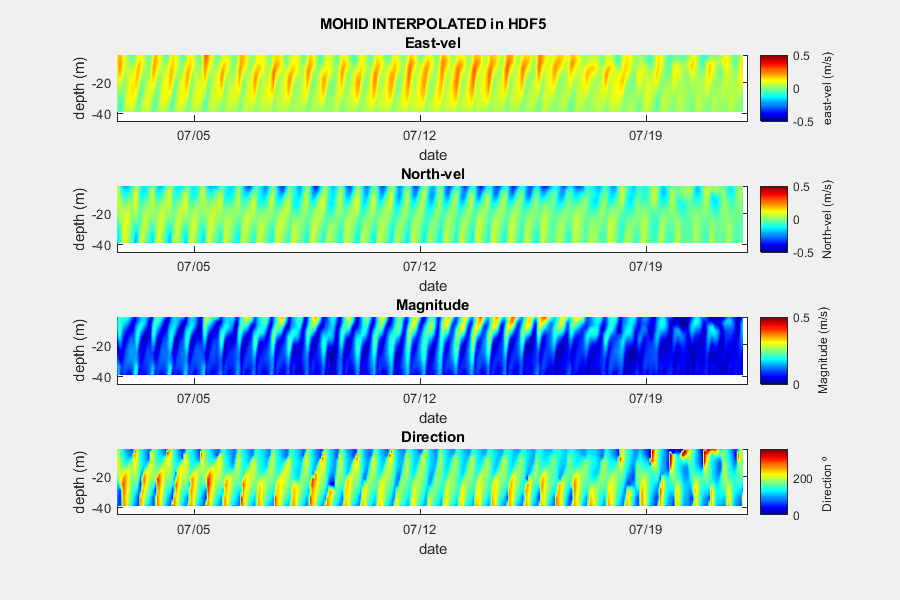


 plot_vertical_profile_time_all_vars(X_adcp,Y_adcp,uqq_mh,vqq_mh,modqq_mh,dirqq_mh,y_lim,c_lim,'MOHID INTERPOLATED in HDF5')
print([path_images 'Profile_MOHID_allVariables'],'-dpng','-r0')

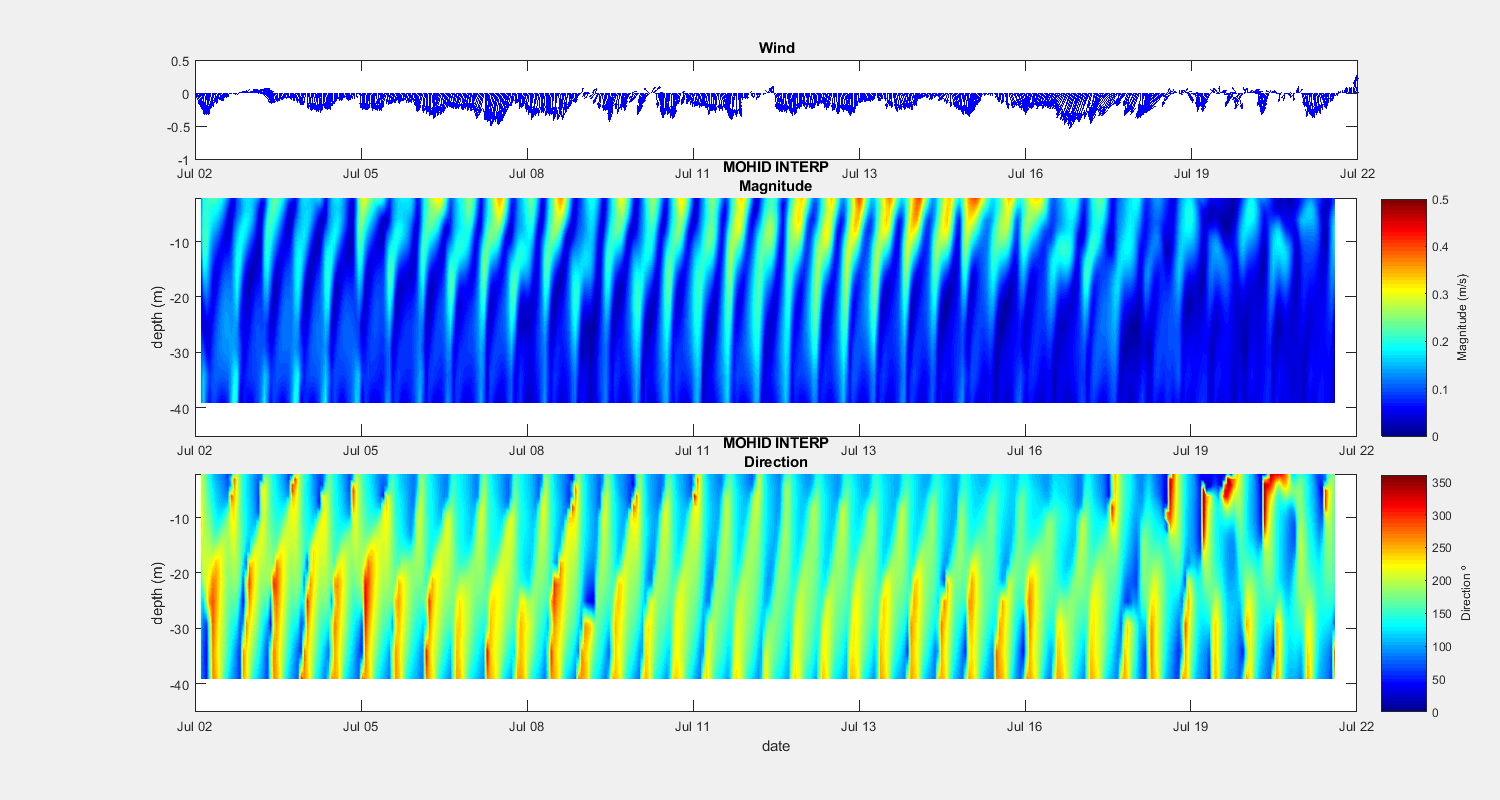



 plot_vertical_profile_time_all_vars_plus_wind(X_adcp,Y_adcp,modqq_mh,dirqq_mh,t_win,u_win,v_win,y_lim,c_lim,'MOHID INTERP')
 print([path_images 'Profile_MOHID_allVariables_with_wind'],'-dpng','-r0')

## **Subseting the data up to 30 meters**

We are going to analize the Vertical Profile up to 30 meters depth to 

you can change at any depth you want. 

ref_depth=30;
ny=find(Y_adcp(:,1)>=-ref_depth );
[qX_adcp,qY_adcp,qu_mh,qv_mh,qvel_mh,qdir_mh]=subset_data_depth(X_adcp,Y_adcp,uqq_mh,vqq_mh,modqq_mh,dirqq_mh,ny(:,1));
[qX_adcp,qY_adcp,qu_adcp,qv_adcp,qvel_adcp,qdir_adcp]=subset_data_depth(X_adcp,Y_adcp,u_adcp,v_adcp,mod_adcp,dir_adcp,ny(:,1));

[bias_30,RMSE_30,R_30]=stats_profile_depth(qvel_adcp,qvel_mh);


**VALIDATE EACH VARIABLE MOHID Vs ADCP**

compare the entire profile with the ADCP and take the average over depth to compute the RMSE and give you the correlation coeficient.

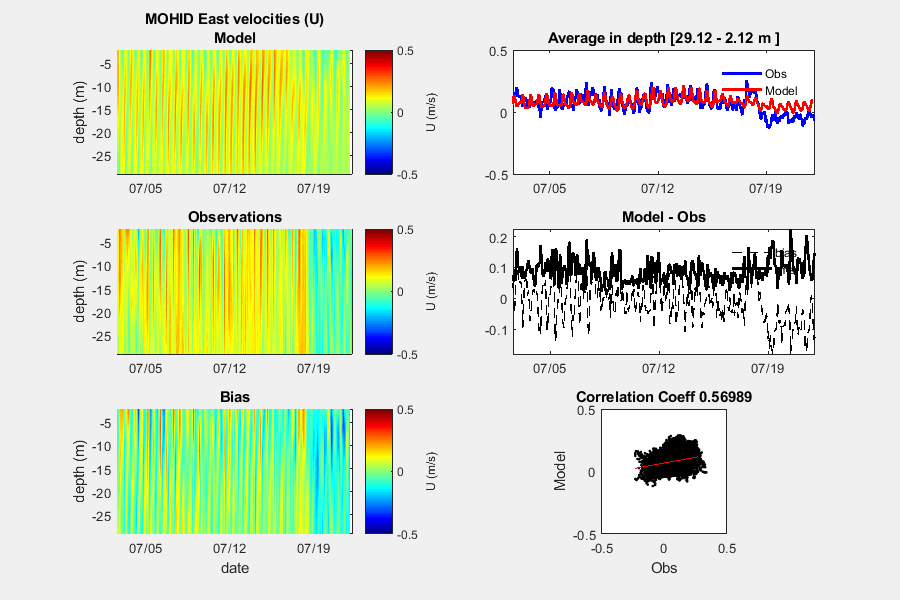

%plot_compare_variableSTAT(qX_adcp,qY_adcp,qvel_mh,qvel_adcp,'MOHID Magnitude','Magnitude (m/s)',y_lim,[0 0.5])
%print([path_images 'obsVsmod-Mag'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

%plot_compare_variableSTAT(qX_adcp,qY_adcp,qdir_mh,qdir_adcp,'MOHID Direction','Direction º ',y_lim,[0 360])
%print([path_images 'obsVsmod-Dir'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

plot_compare_variableSTAT(qX_adcp,qY_adcp,qu_mh,qu_adcp,'MOHID East velocities (U)','U (m/s)',y_lim,[-0.5 0.5 ])
print([path_images 'obsVsmod-U'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

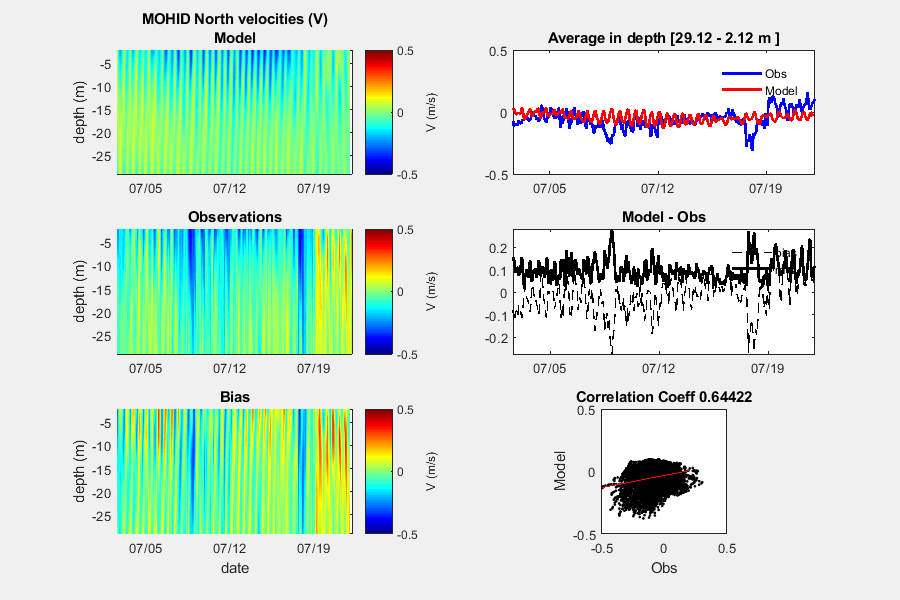


plot_compare_variableSTAT(qX_adcp,qY_adcp,qv_mh,qv_adcp,'MOHID North velocities (V)','V (m/s)',y_lim,[-0.5 0.5 ])
print([path_images 'obsVsmod-V'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

## Plot all Vertical Profiles

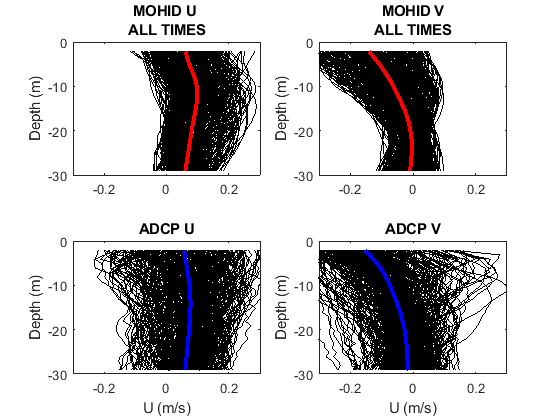


figure
subplot(2,2,1)
plot_vertical_profile_depth(qu_mh,qY_adcp,{'MOHID U ' ; 'ALL TIMES'},'',[-0.3 0.3],'r')
subplot(2,2,2)
plot_vertical_profile_depth(qv_mh,qY_adcp,{'MOHID V' ; 'ALL TIMES'},'',[-0.3 0.3],'r')
subplot(2,2,3)
plot_vertical_profile_depth(qu_adcp,qY_adcp,{'ADCP U' ; },'U (m/s)',[-0.3 0.3],'b')
subplot(2,2,4)
plot_vertical_profile_depth(qv_adcp,qY_adcp,{'ADCP V' ; },'U (m/s)',[-0.3 0.3],'b')
print([path_images 'obsVssmod-UV-depth-alltimes'],'-dpng','-r0')

## Separet vetrtical profile from Low tide Vs High tide

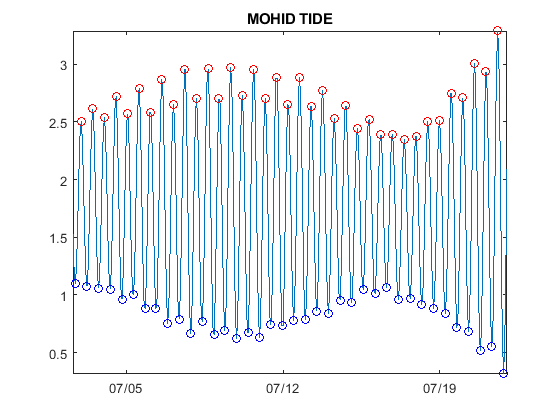

%Find all peaks for High and low  tide
[pks,locs] = findpeaks(wlqq_mh);
[Maxima,MaxIdx] = findpeaks(wlqq_mh);
DataInv = 1.01*max(wlqq_mh) - wlqq_mh;
[Minima,MinIdx] = findpeaks(DataInv);


figure
plot(qX_adcp(1,:),wlqq_mh,qX_adcp(1,MaxIdx),wlqq_mh(MaxIdx),'or')
hold on
plot(qX_adcp(1,MinIdx),wlqq_mh(MinIdx),'ob')
datetick('x')
title('MOHID TIDE')
axis tight
print([path_images 'Time Series'],'-dpng','-r0')

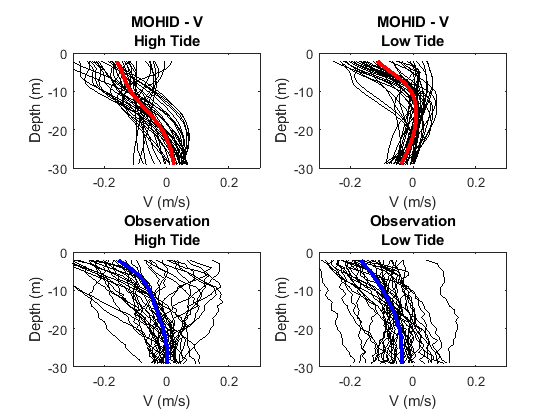


figure
plot_compare_vertical_profile_time(qv_adcp,qv_mh,qY_adcp,MaxIdx,MinIdx,'MOHID - V' ,'V (m/s)',[-0.3 0.3 ])
print([path_images 'obsVsmod-V-depth'],'-dpng','-r0')

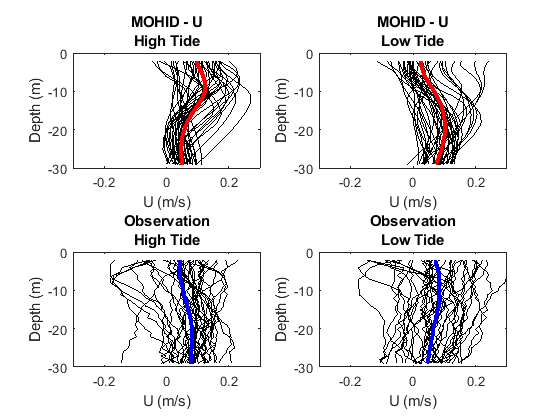

figure
plot_compare_vertical_profile_time(qu_adcp,qu_mh,qY_adcp,MaxIdx,MinIdx,'MOHID - U' ,'U (m/s)',[-0.3 0.3 ])
print([path_images 'obsVsmod-U-depth' ],'-dpng','-r0')

%figure
% plot_compare_vertical_profile_time(qvel_adcp,qvel_mh,qY_adcp,MaxIdx,MinIdx,'MOHID - Magnitude' ,'Mag (m/s)',[0 0.3 ])
% print('obsVsmod-Dir-depth','-dpng','-r0')
% figure
% plot_compare_vertical_profile_time(qdir_adcp,qdir_mh,qY_adcp,MaxIdx,MinIdx,'MOHID - Direction' ,'Dir ',[0 360 ])
% print('obsVsmod-Mag','-dpng','-r0')

## Subset only till 15 meters

%ny=find(Y_adcp(:,1)>=-30);
ref_depth=15;
ny=find(Y_adcp(:,1)>=-ref_depth );
[qX_adcp,qY_adcp,qu_mh,qv_mh,qvel_mh,qdir_mh]=subset_data_depth(X_adcp,Y_adcp,uqq_mh,vqq_mh,modqq_mh,dirqq_mh,ny(:,1));
[qX_adcp,qY_adcp,qu_adcp,qv_adcp,qvel_adcp,qdir_adcp]=subset_data_depth(X_adcp,Y_adcp,u_adcp,v_adcp,mod_adcp,dir_adcp,ny(:,1));

[bias_15,RMSE_15,R_15]=stats_profile_depth(qvel_adcp,qvel_mh);

## Compare each Variable Separate

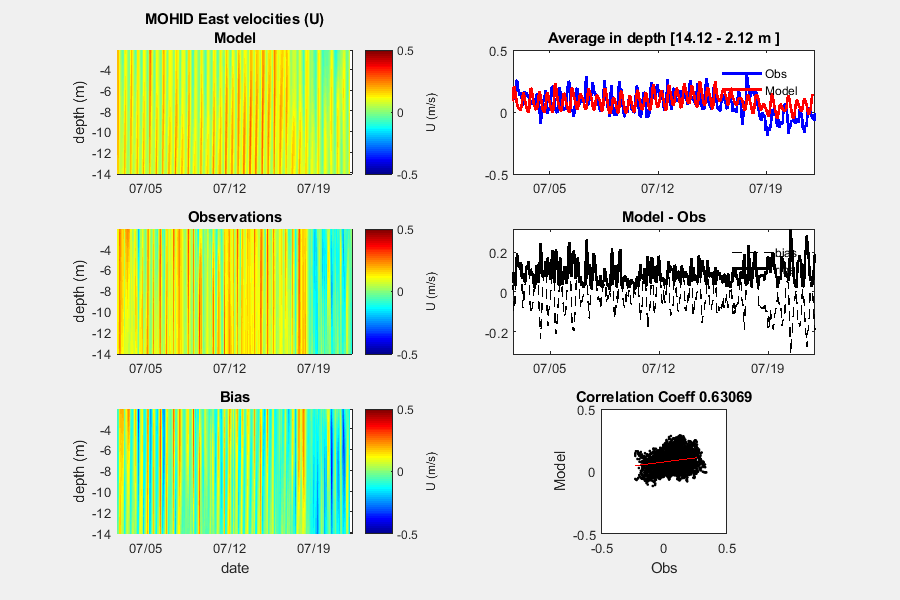

%plot_compare_variableSTAT(qX_adcp,qY_adcp,qvel_mh,qvel_adcp,'MOHID Magnitude','Magnitude (m/s)',y_lim,[0 0.5])
%print(['obsVsmod-Mag'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

%plot_compare_variableSTAT(qX_adcp,qY_adcp,qdir_mh,qdir_adcp,'MOHID Direction','Direction º ',y_lim,[0 360])
%print(['obsVsmod-Dir'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')


plot_compare_variableSTAT(qX_adcp,qY_adcp,qu_mh,qu_adcp,'MOHID East velocities (U)','U (m/s)',y_lim,[-0.5 0.5 ])
print([path_images 'obsVsmod-U'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

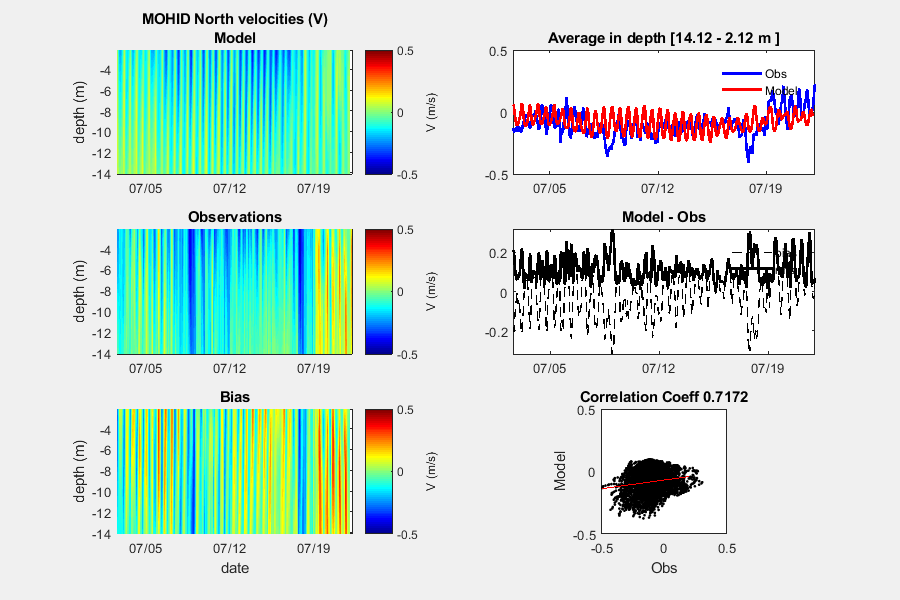


plot_compare_variableSTAT(qX_adcp,qY_adcp,qv_mh,qv_adcp,'MOHID North velocities (V)','V (m/s)',y_lim,[-0.5 0.5 ])
print([path_images 'obsVsmod-V'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')



%plot_all_variables(qX_adcp,qY_adcp,qu_mh,qv_mh,qvel_mh,qu_adcp,qv_adcp,qvel_adcp,'MOHID depth [0- 15 m]',y_lim,c_lim)

## Subset only > 15 m till 30 m

ny=find(Y_adcp(:,1)>=-30 & Y_adcp(:,1)<-15 );
[qX_adcp,qY_adcp,qu_mh,qv_mh,qvel_mh,qdir_mh]=subset_data_depth(X_adcp,Y_adcp,uqq_mh,vqq_mh,modqq_mh,dirqq_mh,ny(:,1));
[qX_adcp,qY_adcp,qu_adcp,qv_adcp,qvel_adcp,qdir_adcp]=subset_data_depth(X_adcp,Y_adcp,u_adcp,v_adcp,mod_adcp,dir_adcp,ny(:,1));
[bias_15,RMSE_15,R_15]=stats_profile_depth(qvel_adcp,qvel_mh);
%plot_all_variables(qX_adcp,qY_adcp,qu_mh,qv_mh,qvel_mh,qu_adcp,qv_adcp,qvel_adcp,'MOHID depth [15 - 30 m]',y_lim,c_lim)

## Compare each Variable  and get the STATISTIC

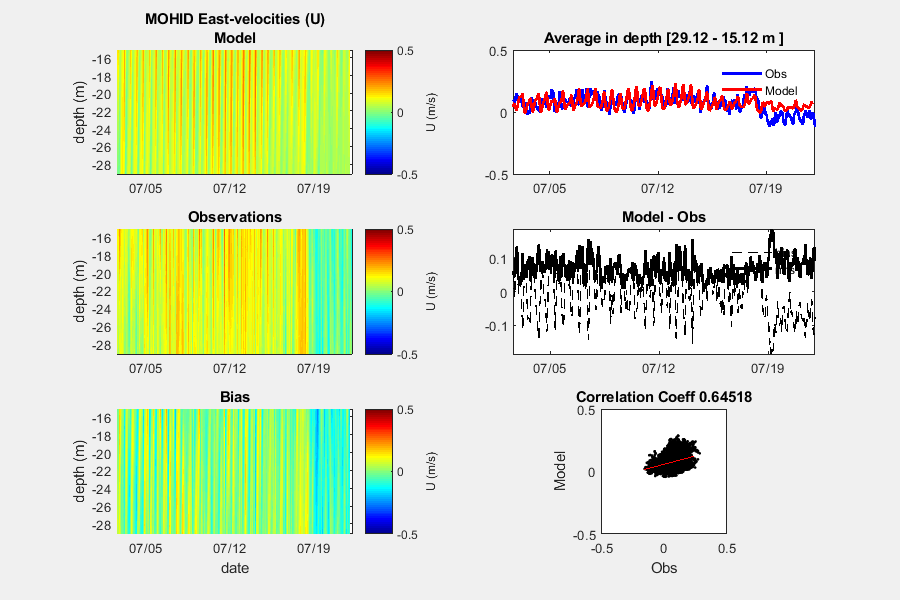

%plot_compare_variableSTAT(qX_adcp,qY_adcp,qvel_mh,qvel_adcp,'MOHID Magnitude','Magnitude (m/s)',y_lim,[0 0.5])
%print(['obsVsmod-Mag'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

%plot_compare_variableSTAT(qX_adcp,qY_adcp,qdir_mh,qdir_adcp,'MOHID Direction','Direction º ',y_lim,[0 360])
%print(['obsVsmod-Dir'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

plot_compare_variableSTAT(qX_adcp,qY_adcp,qu_mh,qu_adcp,'MOHID East-velocities (U)','U (m/s)',y_lim,[-0.5 0.5 ])
print([path_images 'obsVsmod-U'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')

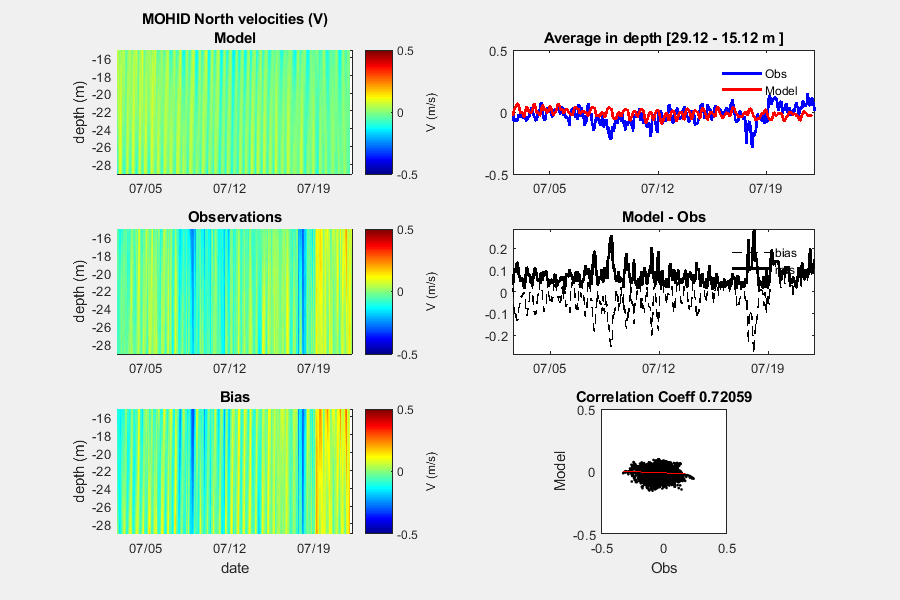


plot_compare_variableSTAT(qX_adcp,qY_adcp,qv_mh,qv_adcp,'MOHID North velocities (V)','V (m/s)',y_lim,[-0.5 0.5 ])
print([path_images 'obsVsmod-V'  num2str(min(qY_adcp(:))) num2str(max(qY_adcp(:))) '.png'],'-dpng','-r0')


% figure
% nm=1
% subplot(3,1,1)
% quiver(datenum(t_win)',zeros(size(u_win)),u_win,v_win,'b');
% title('WIND')
%  datetick('x')
%  axis tight
%  ylim([-0.5 0.5])
% subplot(3,1,2)
% quiver(qX_adcp(nm,:), zeros(size(qu_adcp(nm,:))), qu_adcp(nm,:),qv_adcp(nm,:),'k');
% title('ADCP')
% %plot(adcp.mtime(1:end-3),adcp.heading(1:end-3))
%  datetick('x')
%  axis tight
%  ylim([-0.5 0.5])
% subplot(3,1,3)
% quiver(X_adcp(nm,:), zeros(size(qu_mh(nm,:))), qu_mh(nm,:),qv_mh(nm,:),'r');
% title('MOHID')
% 
% %plot(t_ts,wl_ts(1,:)-mean(wl_ts(1,:)),'g')
%  datetick('x')
%  %legend('win','adcp','mohid')
% axis tight
% ylim([-0.5 0.5])

close all

figure plot(X_adcp(1,:),bias,'k') hold on plot(X_adcp(1,:),RMSE,'k.-') datetick('x') ylim([-0.5 0.5]) yyaxis right plot(X_adcp(1,:),R_t) datetick('x')

figure plot_vertical_profile_time_all_vars(X_adcp,Y_adcp,qu_mh,qv_mh,qvel_mh,qdir_mh,y_lim,c_lim,'MOHID INTERP Time Series- July 2009') figure plot_vertical_profile_time_all_vars(X_adcp,Y_adcp,qu_adcp,qv_adcp,qvel_adcp,qdir_adcp,y_lim,c_lim,'ADCP Time Series- July 2009')

## Figure U

## Start statistics

figure subplot(3,2,1) plot_vertical_profile_time(qX_adcp,qY_adcp,qvel_mh,y_lim,[0 0.5],{'MOHID- Depth ';'Magnitude'},'Magnitude (m/s)')

subplot(3,2,2) hidden_arrow = compass(1,0);%I don't care the direction hidden_arrow.Color = 'none'; hold on compass(qu_mh,qv_mh) title('Model') subplot(3,2,3) plot_vertical_profile_time(qX_adcp,qY_adcp,qvel_adcp,y_lim,[0 0.5],'ADCP','Magnitude (m/s)') subplot(3,2,4) hidden_arrow = compass(1,0);%I don't care the direction hidden_arrow.Color = 'none'; hold on compass(qu_adcp,qv_adcp) title('Obs')

subplot(3,2,5) plot_vertical_profile_time(qX_adcp,qY_adcp,qvel_adcp-qvel_mh,y_lim,[0 0.5],'BIAS','Magnitude (m/s)')

subplot(3,2,6) plot(qX_adcp(1,:),mean(qvel_adcp),'b','linewidth',2) hold on plot(qX_adcp(1,:),mean(qvel_mh),'r','linewidth',2) legend('Obs','Model') datetick('x') title('average in depth') axis tight

%% 

%% Plot MOHID data figure subplot(2,1,1) plot_vertical_profile_time(X_adcp,Y_adcp,u_mohid,y_lim,c_lim,' MOHID U','east-vel (m/s)') subplot(2,1,2) plot_vertical_profile_time(X_mohid,Y_mohid,v_mohid,y_lim,c_lim,'MOHID V ','north-vel (m/s)')

%% [X2_ts,Y2_ts]=meshgrid(t_ts,depth); y_lim=[-40 0]; c_lim=[-0.5 0.5]; subplot(2,1,1) plot_vertical_profile_time(datenum(X2_ts),-Y2_ts,u_ts',y_lim,c_lim,' MOHID U','east-vel (m/s)') subplot(2,1,2) plot_vertical_profile_time(X_adcp,Y_adcp,adcp.east_vel(:,1:end-1),y_lim,c_lim,' ADCP EAST VELOCITY ','east-vel (m/s)')

%% subplot(2,1,1) plot_vertical_profile_time(datenum(X2_ts),-Y2_ts,v_ts',y_lim,c_lim,' MOHID V','north-vel (m/s)') subplot(2,1,2) plot_vertical_profile_time(X_adcp,Y_adcp,adcp.north_vel(:,1:end-1),y_lim,c_lim,'ADCP NORTH VELOCITY ','north-vel (m/s)')

%% subplot(2,1,1) plot_vertical_profile_time(datenum(X2_ts),-Y2_ts,mod_ts',y_lim,c_lim,'MOHID MODULUS ','(m/s)') subplot(2,1,2) plot_vertical_profile_time(X_adcp,Y_adcp,adcp_mod,y_lim,c_lim,'ADCP MODULUS ','(m/s)')

%% y_lim=[-10 0]; c_lim=[0 360] subplot(2,1,1) plot_vertical_profile_time(datenum(X2_ts),-Y2_ts,deg_ts',y_lim,c_lim,'MOHID DEGREES ','Depth') subplot(2,1,2) plot_vertical_profile_time(X_adcp,Y_adcp,dir_adcp+180,y_lim,c_lim,'ADCP DEGREES ','Depth')

%% compass(u,v) %% Visual Comparison MOHID Vs ADCP over time x_lim=[]; y_lim=[-40 0]; c_lim=[0 0.4];

figure subplot(5,2,[1 2]) plot(time_mohid,wl_mohid- mean(wl_mohid),'k','linewidth',2) ylabel('water level (m)') title('MOHID Water Level') datetick('x') %plot ADCP subplot(5,2,[3 6]) plot_vertical_profile_time(X2_mohid,Y2_mohid,mod_i_time,y_lim,c_lim,'MOHID','Velocity Modulus (m/s)') %plot ADCP subplot(5,2,[7 10]) plot_vertical_profile_time(X_adcp,Y_adcp,adcp_mod,y_lim,c_lim,'ADCP','Velocity Modulus (m/s)')

%% %% Movie evolution in time figure for t=1:length(adcp.mtime(1:end-1)) plot(mod_i_time(:,t),dp) hold on plot(adcp_mod(:,t),adcp.config.ranges)

xlim([0 0.5]) ylim([-35 0]) legend('mohid','adcp') title(datestr(adcp.mtime(t))) xlabel('Velocity Modulus (m/s)') ylabel('depths (m)') drawnow hold off end %% Plot 

figure subplot(2,1,1) plot(mod_i_time,dp) xlim([0 0.5]) ylim([-35 0]) subplot(2,1,2) plot(adcp_mod,adcp.config.ranges) xlim([0 0.5]) ylim([-35 0])